## 1. Image Loading

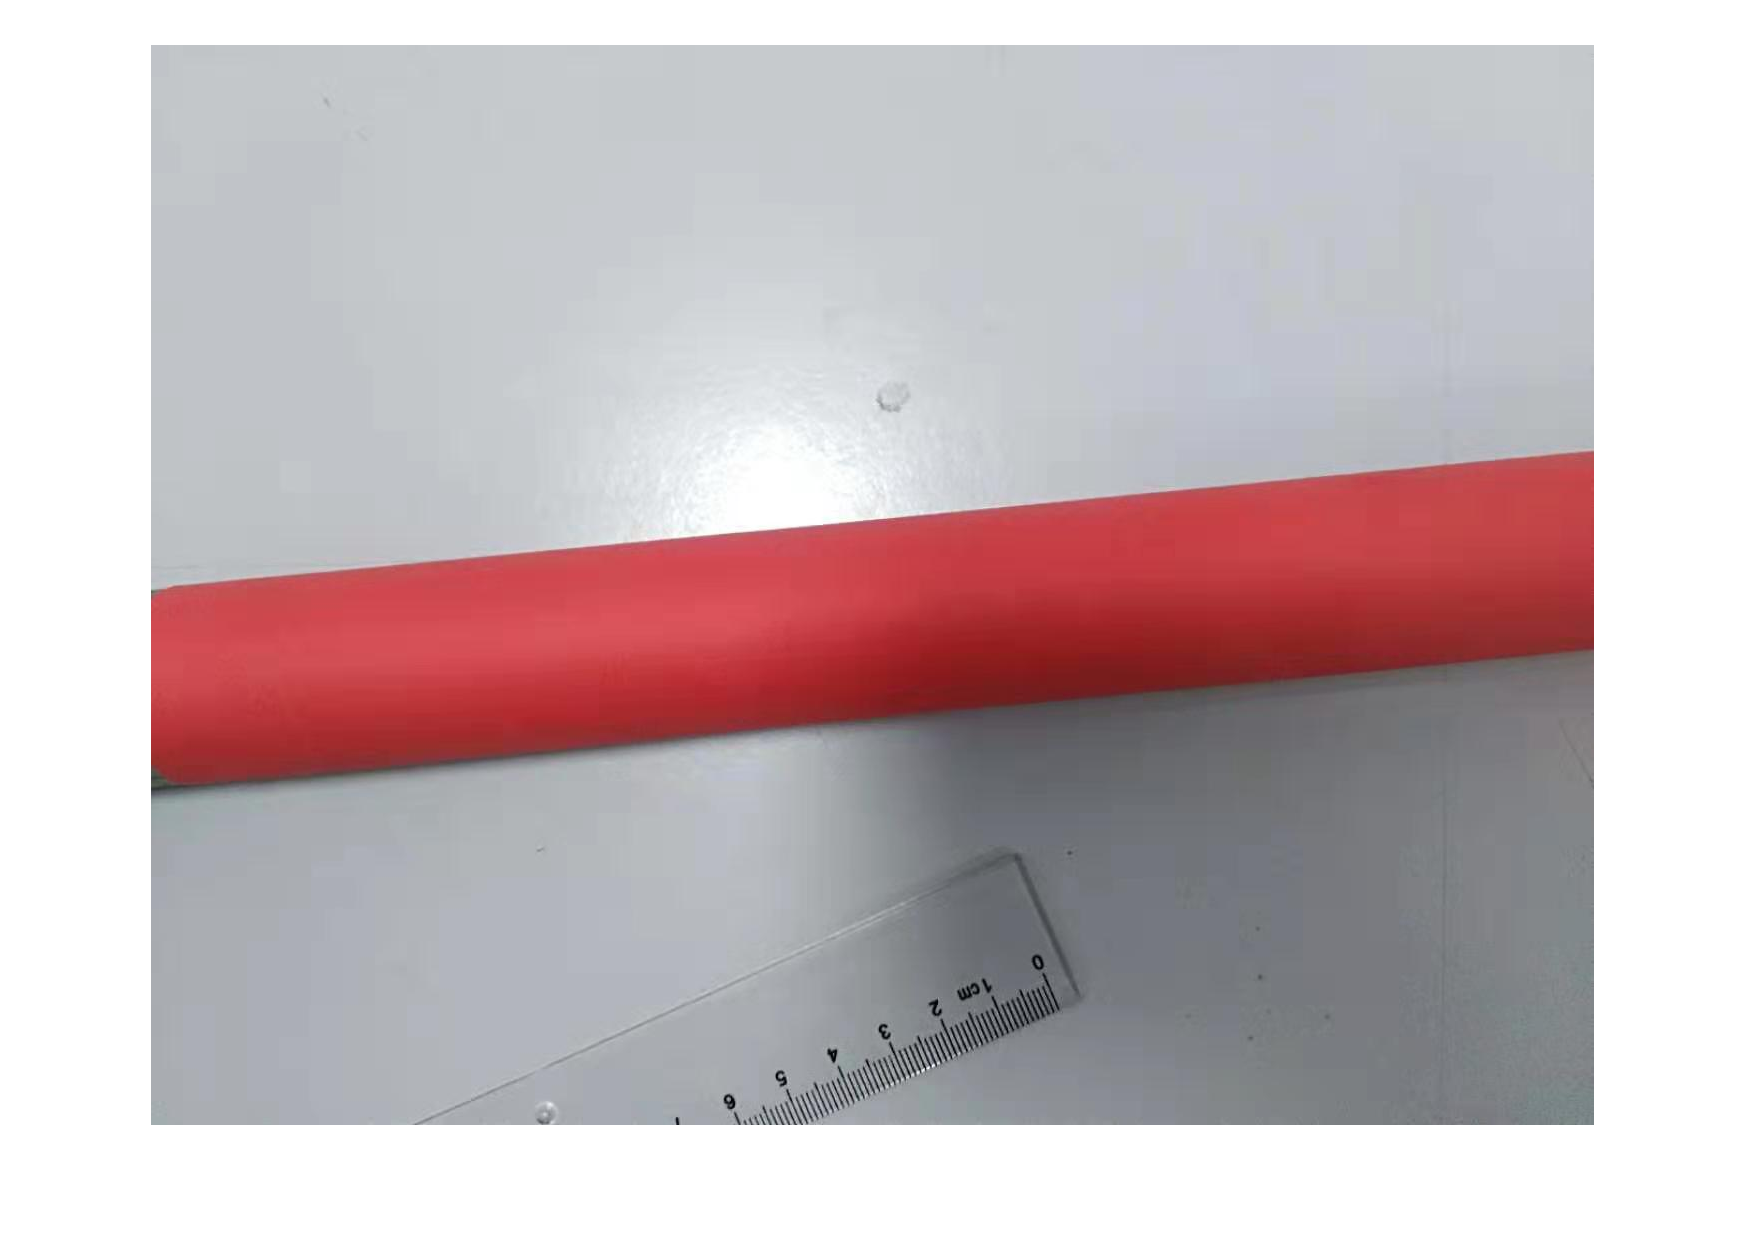

img = imread("./data/3.jpg");
img = im2double(img);

figure, imshow(img);

## 2. Initial Points

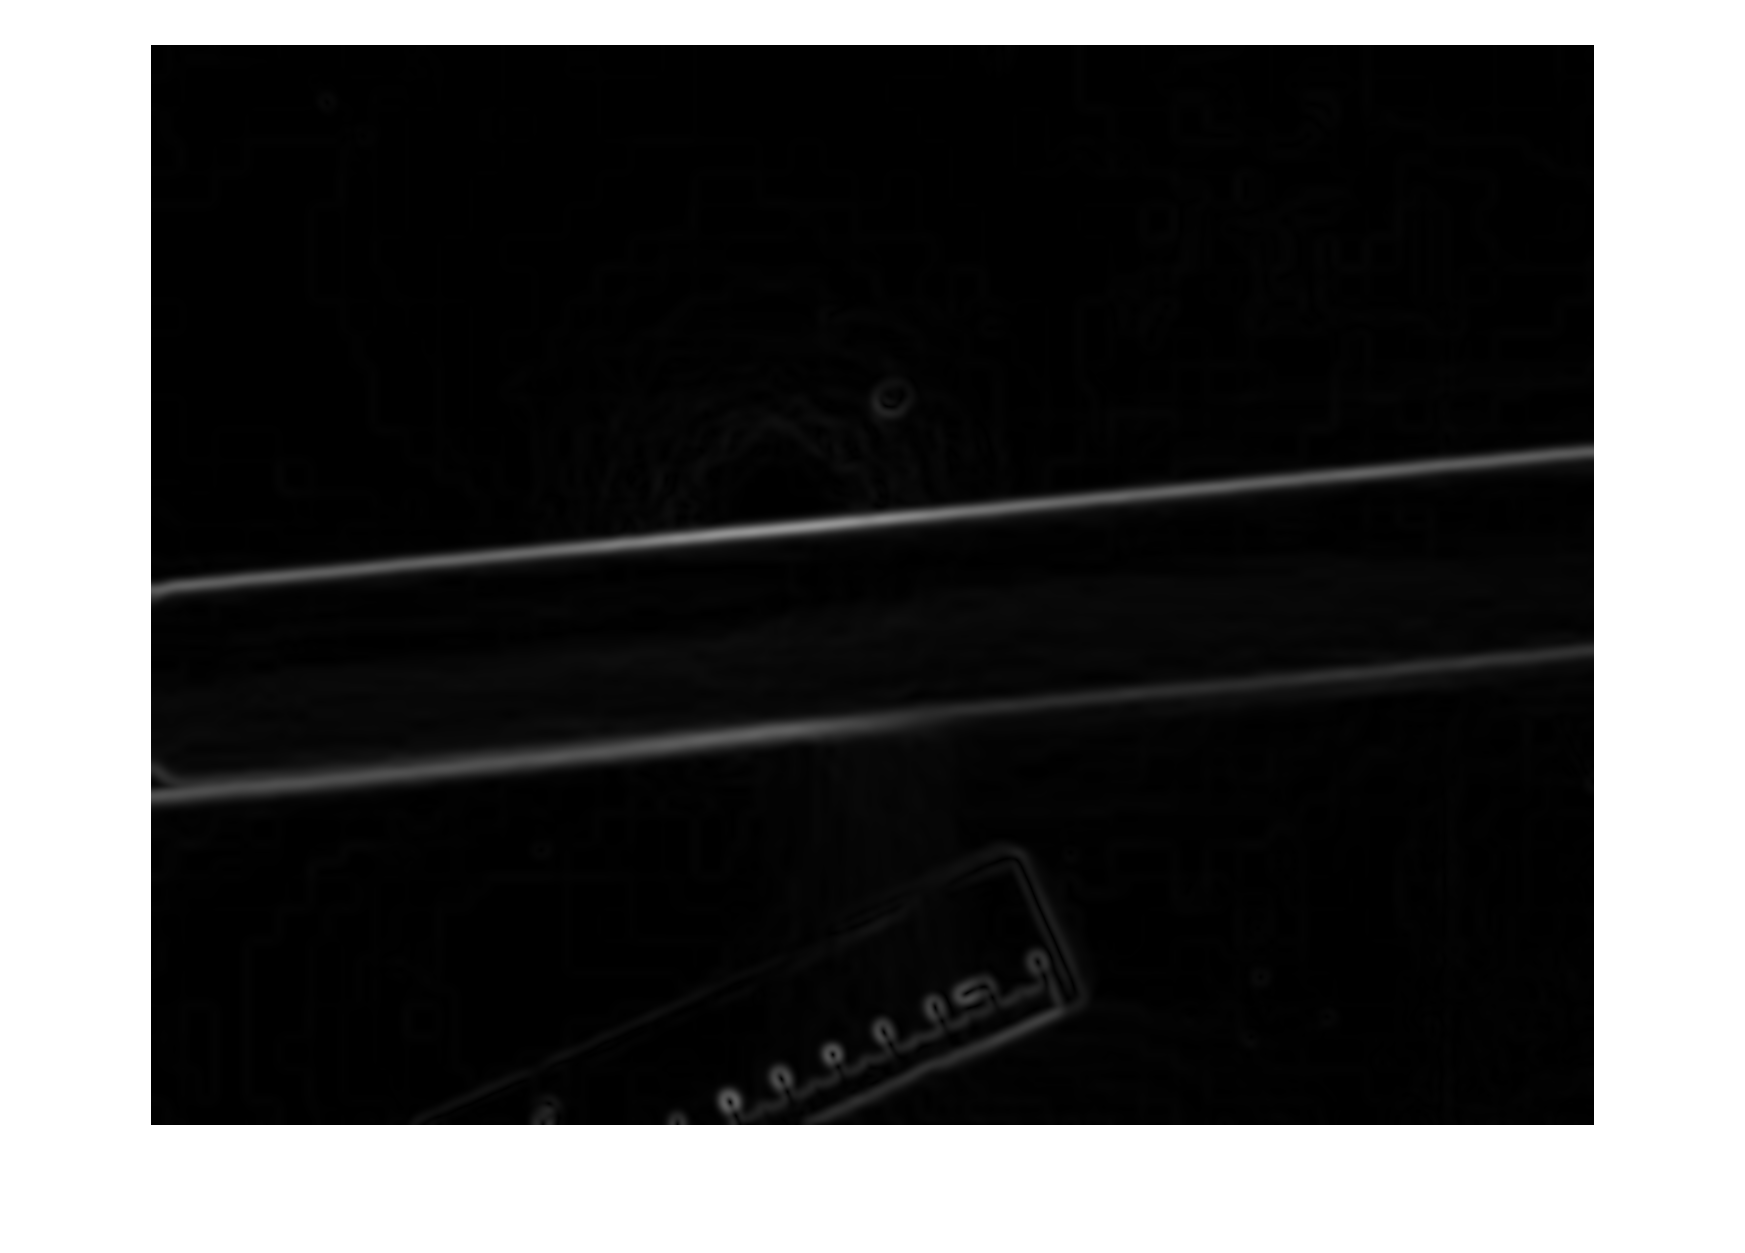

edges = compute_edges(img,5);

figure, imshow(edges);

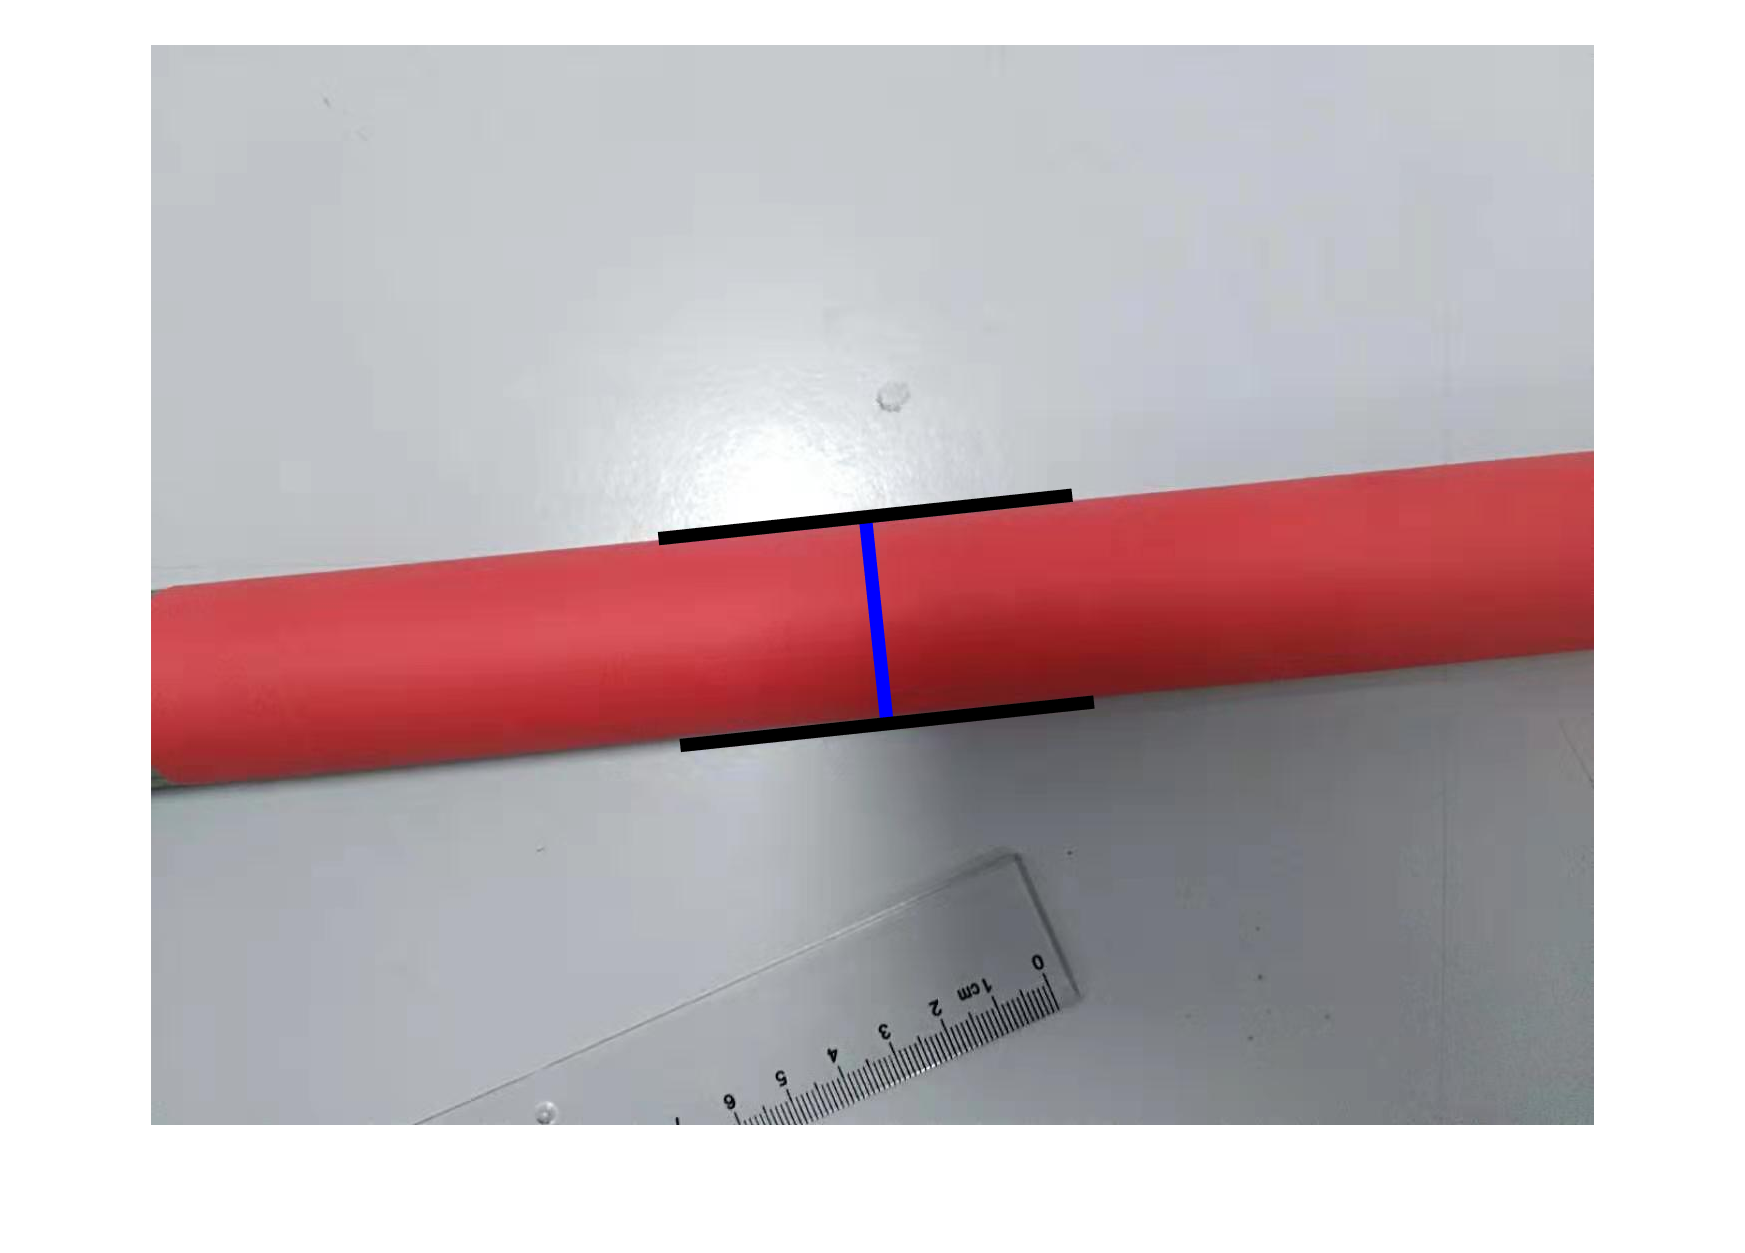

[p1, p2] = initial_points(edges);

figure, imshow(img), hold on
plot_ruler(p1,p2);

## 3. Gradient Decent

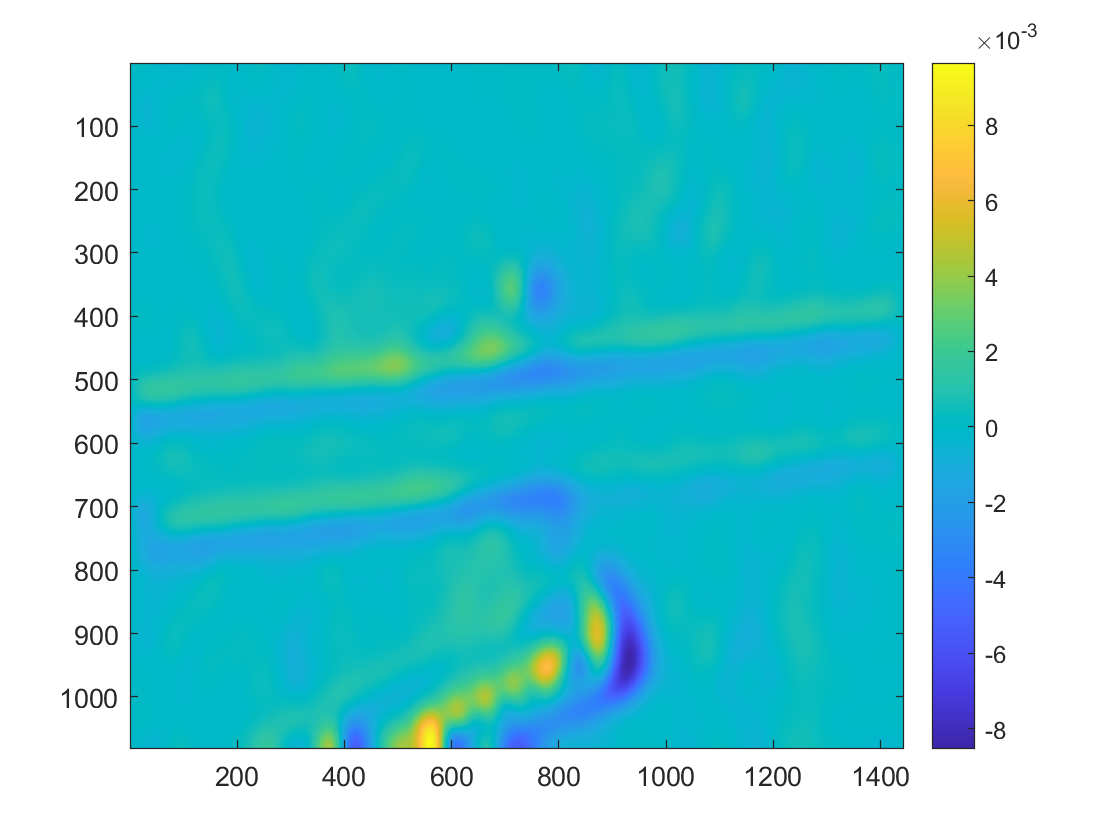

grad = compute_grad(edges,25);

figure, imagesc(grad(:,:,1)), colorbar;

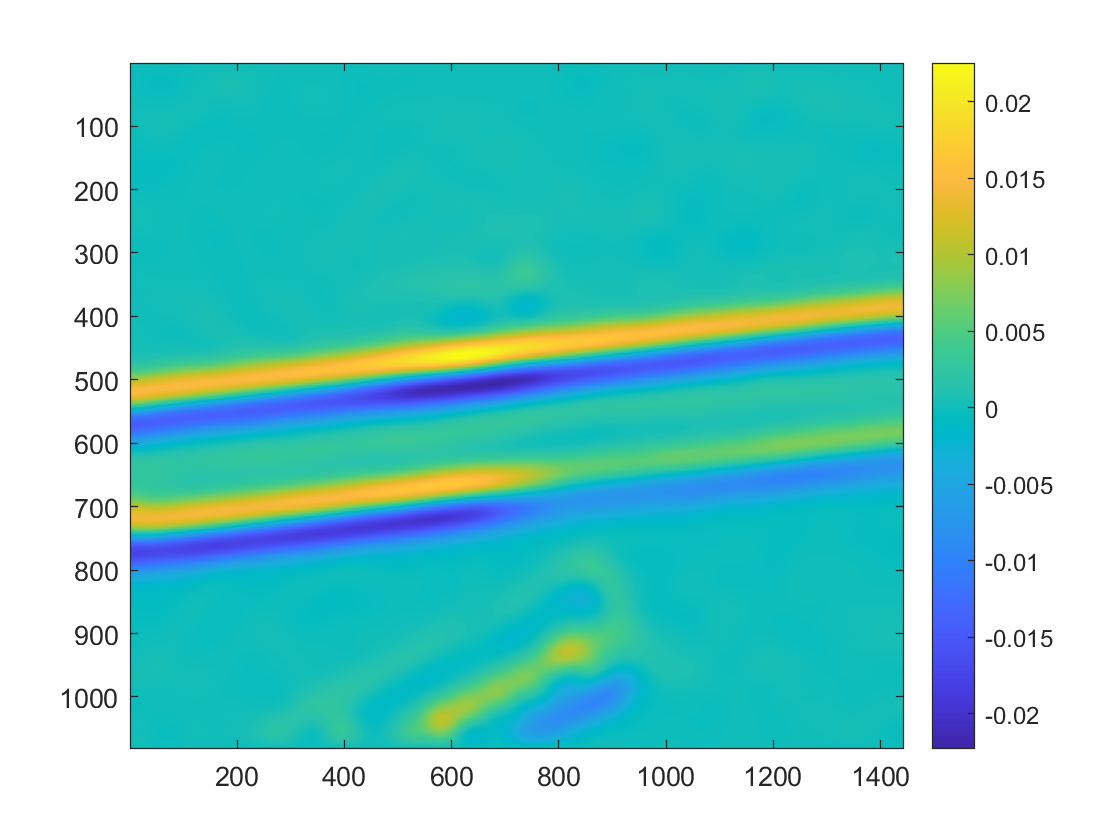

figure, imagesc(grad(:,:,2)), colorbar;

figure, imshow(img), hold on
plot_ruler(p1,p2);

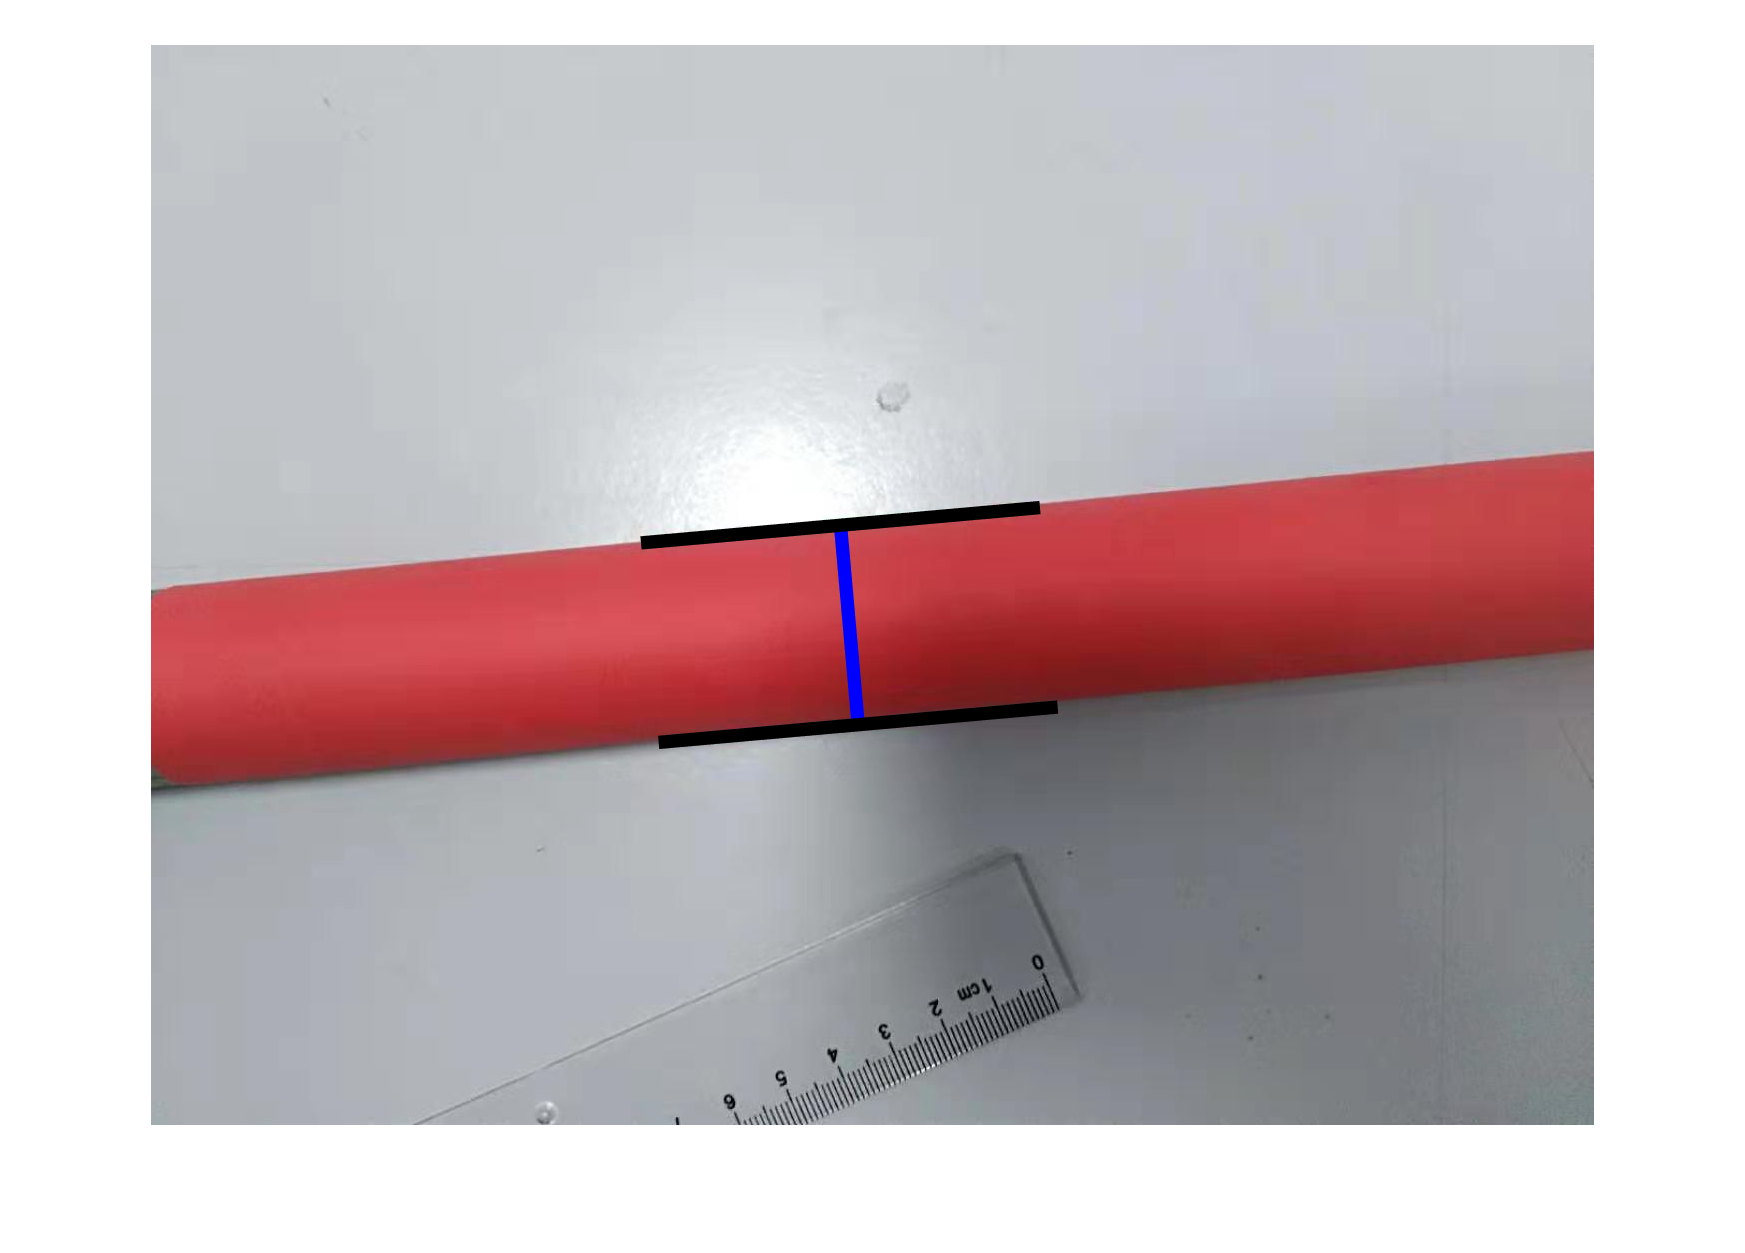

v1 = 0.0;
v2 = 0.0;
[p1,p2,v1,v2,steps,D,dD] = gradient_decent(grad,p1,p2,v1,v2);

figure, imshow(img), hold on
plot_ruler(p1,p2);


steps

steps = 9

result = D

result = 200.2516

uncertainty = dD

uncertainty = 0.1827